# **Task_03:   Simulate** Multi Tuned Mass Dampers (MTMDs)

The system that we'll explore is shown below.  NOTE the following:

- We have 3 ***primary*** masses - $m_1 \;,m_2 \;\;,m_3$

- The degrees of freedom are - $z_1 \;,z_2 \;\;,z_3$ 

- Each dof is measured from an INERTIAL frame coinciding with the UNstretched spring positions

- We have a "road patch" that can move - $z_G$

- We have 3 springs, and although they have not been drawn each spring has a damper in parallel.

- The UN stretched lengths of each spring are - $L_G \;\;,L_1 \;\;,L_2$

- Each ***primary*** mass is acted upon by an external force - $F_1 \;\;,F_2 \;\;,F_3$

- Each ***primary*** mass has a companion Tuned Mass Damper (TMD) -  $\left(m_a ,k_a \right),\;\left(m_b ,k_b \right),\;\left(m_c ,k_c \right),$

- The UN stretched lengths of each TMD spring are - $L_a \;\;,L_b \;\;,L_c$

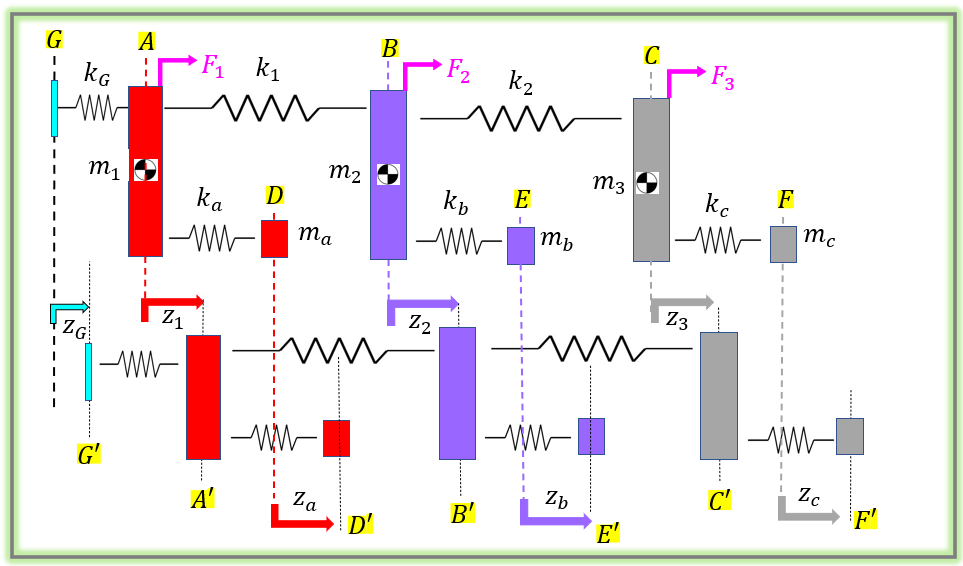

## Newton derivation of the Mechanical Equations of motion

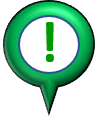The Newton 2nd Law derivation is summarized in the function file:

- [`bh_TASK_01_3dof_tmd_derive.mlx`](matlab: edit bh_TASK_01_3dof_tmd_derive.mlx)

## Clear your workspace

clear

## Model parameters

Consult database for parameters 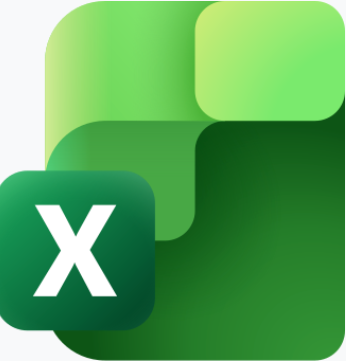 :

- See: [` bh_smd_3dof_tmd_params_CLS.m `](matlab:  open  bh_smd_3dof_tmd_params_CLS.m)

% param_DB = bh_smd_3dof_tmd_params_CLS();
% param_DB = bh_smd_3dof_tmd_params_CLS("bh_smd_3dof_tmd_params_database.xlsx", "CONFIG_2");
% param_DB = bh_smd_3dof_tmd_params_CLS("bh_smd_3dof_tmd_params_database.xlsx", "CONFIG_3");
param_DB = bh_smd_3dof_tmd_params_CLS("bh_smd_3dof_tmd_params_database.xlsx", "CONFIG_FLEX");

Masses:

params_T.m1 = param_DB.m1;  % (kg)
params_T.m2 = param_DB.m2;  % (kg)
params_T.m3 = param_DB.m3;  % (kg)

params_T.ma = param_DB.ma; % 1e-4;  % (kg)
params_T.mb = param_DB.mb; % 1e-4;  % (kg)
params_T.mc = param_DB.mc; % 1e-4;  % (kg)

Spring Stiffness:

params_T.k1 = param_DB.k1;   % (N/m)
params_T.k2 = param_DB.k2;   % (N/m)
params_T.kG = param_DB.kG;   % (N/m)

Solve for the **BASELINE** case - i.e.:  no TMDs

[w2_baseline_list, ~] = bh_newton_smd_3dof_eig(  params_T.m1, params_T.m2, params_T.m3, ...
                                                 params_T.kG, params_T.k1, params_T.k2 );
w_baseline = sqrt(w2_baseline_list)

w_baseline =     6.9531
   19.4822
   28.1526


Spring Stiffness - for the  TMDs

We'll explore the design strategy that was suggested in [`bh_TASK_02_smd_3dof_TMD_derive.mlx`](matlab:open('./bh_TASK_02_smd_3dof_TMD_derive.mlx')) 

- to attenuate $\omega_1$ consider a TMD that strongly influences $z_3$     ${\Longrightarrow \;\;k}_c =m_c \ldotp \omega_1^2$

- to attenuate $\omega_2$ consider a TMD that strongly influences $z_1$     ${\Longrightarrow \;\;k}_a =m_a \ldotp \omega_2^2$

- to attenuate $\omega_3$ consider a TMD that strongly influences $z_2$     ${\Longrightarrow \;\;k}_b =m_b \ldotp \omega_3^2$

params_T.ka = params_T.ma * w2_baseline_list(2);   % (N/m)
params_T.kb = params_T.mb * w2_baseline_list(3);   % (N/m)
params_T.kc = params_T.mc * w2_baseline_list(1);   % (N/m)
%-----------------------------------------------------------------
% params_T.ka = params_T.ma * w2_baseline_list(1);   % (N/m)
% params_T.kb = params_T.mb * w2_baseline_list(1);   % (N/m)
% params_T.kc = params_T.mc * w2_baseline_list(1);   % (N/m)
%-----------------------------------------------------------------
% params_T.ka = params_T.ma * w2_baseline_list(1);   % (N/m)
% params_T.kb = params_T.mb * w2_baseline_list(2);   % (N/m)
% params_T.kc = params_T.mc * w2_baseline_list(3);   % (N/m)
%-----------------------------------------------------------------
% params_T.ka = params_T.ma * w2_baseline_list(3);   % (N/m)
% params_T.kb = params_T.mb * w2_baseline_list(2);   % (N/m)
% params_T.kc = params_T.mc * w2_baseline_list(1);   % (N/m)
%-----------------------------------------------------------------

Spring Damping:

BETA_CONST_PROP_DAMPING = 1e-3;
params_T.c1 =     BETA_CONST_PROP_DAMPING*params_T.k1;    % (N/(m/s))
params_T.c2 =     BETA_CONST_PROP_DAMPING*params_T.k2;    % (N/(m/s))
params_T.cG =     BETA_CONST_PROP_DAMPING*params_T.kG;    % (N/(m/s))

params_T.ca =  10*BETA_CONST_PROP_DAMPING*params_T.ka;    % (N/(m/s))
params_T.cb =  10*BETA_CONST_PROP_DAMPING*params_T.kb;    % (N/(m/s))
params_T.cc =  10*BETA_CONST_PROP_DAMPING*params_T.kc;    % (N/(m/s))

Spring UNstretched Length:

params_T.L1 = param_DB.L1; % (m)
params_T.L2 = param_DB.L2; % (m)
params_T.LG = param_DB.LG;  % (m)

params_T.La = 0.125; % (m)
params_T.Lb = 0.125; % (m)
params_T.Lc = 0.125;  % (m)

## Initial Conditions(NEWTON)

Recall the DOF vector:

- 
$$x^T =\left\lbrack \begin{array}{ccccccc}
\;\;z_1  & z_2  & z_3  & z_a  & z_b  & z_c  & 
\end{array}\right\rbrack$$


Mass ICs

IC_Newt_T.z_col    = [0,0,0,  0,0,0]' ;  % z1,z2,z3, za,zb,zc
IC_Newt_T.zdot_col = [0,0,0,  0,0,0]' ;  % z1,z2,z3, za,zb,zc

Ground patch ICs

IC_Newt_T.zG       = 0;
IC_Newt_T.zG_dot   = 0;

## Initial Conditions(Simscape PRISMATIC joint)

In our Simscape Multibody model, we'll use [`PRISMATIC joints`](https://www.mathworks.com/help/releases/R2024b/sm/ref/prismaticjoint.html) to represent our springs

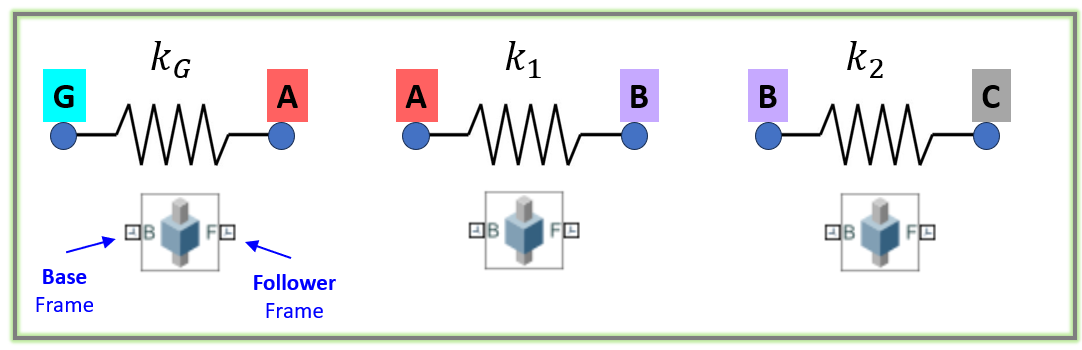

Each spring (our Prismatic joints) needs to be configured with 

- The **position** of the FOLLOWER frame relative to the BASE

- The **velocity** of the FOLLOWER frame relative to the BASE

Which in we can interpret as: 

- **POSITION**:    $\Longrightarrow$     Initial spring length and an 

- **VELOCITY**:    $\Longrightarrow$     Initial spring length rate of change (say velocity) 

We will utilize our Newton Initial Conditions and the UNstretched spring lengths to compute these. 

Consider the following schematic:

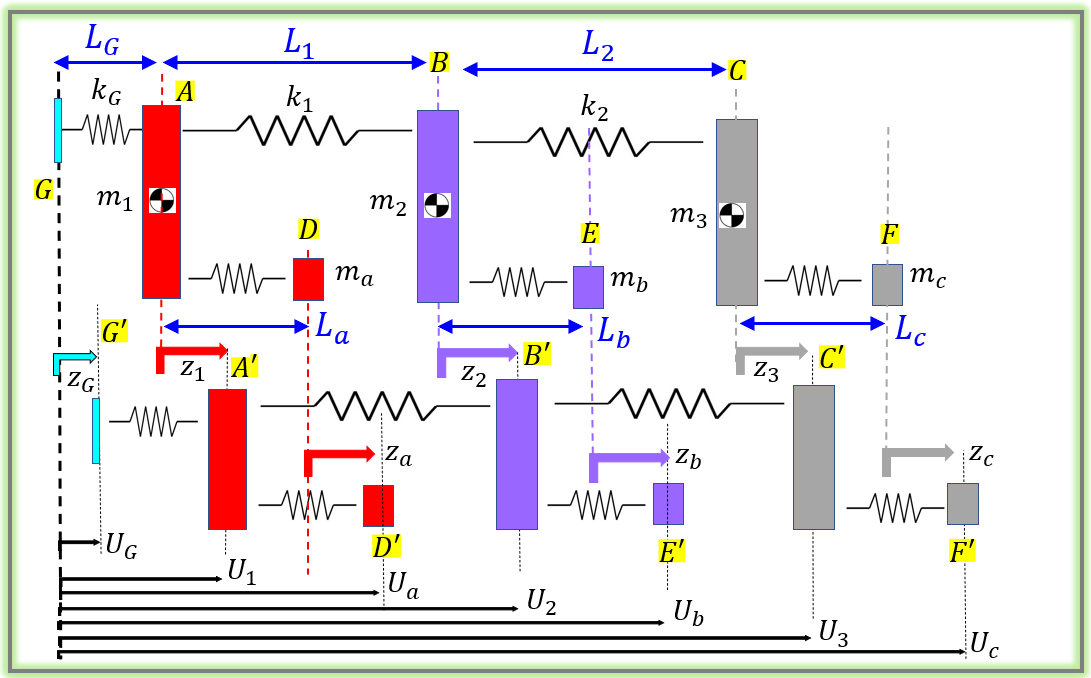

**Focusing first on the primary masses - **$m_1 \;\;,m_2 \;\;,m_3$

From the above figure we can write:

- 
$$U_G =z_G$$


- 
$$U_1 \;=L_G \;+z_1$$


- 
$$U_2 =L_G +L_1 +z_2$$


- 
$$U_3 =L_G \;+L_1 \;+L_2 \;+z_3$$


So the Initial Spring Lengths are:

- 
$$L_{G^{\prime } A^{\prime } } \;=\;U_1 -U_G \;=\;\left(L_G \;+z_1 \right)-\left(z_G \right)\;=\;\;L_G \;+\left(z_1 -z_G \right)$$


- 
$$L_{A^{\prime } B^{\prime } } \;=U_2 \;-U_1 \;\;=\;\left(L_G +L_1 +z_2 \right)-\left(L_G \;+z_1 \right)\;=L_1 \;+\;\left(z_2 -z_1 \right)$$


- 
$$L_{B^{\prime } C^{\prime } } \;=U_3 \;-U_2 \;\;=\;\left(L_G +L_1 +L_2 +z_3 \right)-\left(L_G \;+L_1 +z_2 \right)\;=L_2 \;+\;\left(z_3 -z_2 \right)$$


And similarly the Initial Spring Length rates of change are:

- 
$$\frac{\mathrm{d}}{\mathrm{d}t}\left(L_{G^{\prime } A^{\prime } } \right)\;=\;\;\left({\dot{z} }_1 -{\dot{z} }_G \right)$$


- 
$$\frac{\mathrm{d}}{\mathrm{d}t}\left(L_{A^{\prime } B^{\prime } } \right)\;=\;\;\left({\dot{z} }_2 -{\dot{z} }_1 \right)$$


- 
$$\frac{\mathrm{d}}{\mathrm{d}t}\left(L_{B^{\prime } C^{\prime } } \right)\;=\;\;\left({\dot{z} }_3 -{\dot{z} }_2 \right)$$


Recall the DOF vector:

- 
$$x^T =\left\lbrack \begin{array}{ccccccc}
\;\;z_1  & z_2  & z_3  & z_a  & z_b  & z_c  & 
\end{array}\right\rbrack$$


IC_PrisJ_T.springG.pos = (IC_Newt_T.z_col(1)    - IC_Newt_T.zG) + params_T.LG;
IC_PrisJ_T.springG.vel = (IC_Newt_T.zdot_col(1) - IC_Newt_T.zG_dot);

IC_PrisJ_T.spring1.pos = (IC_Newt_T.z_col(2)    - IC_Newt_T.z_col(1)) + params_T.L1;
IC_PrisJ_T.spring1.vel = (IC_Newt_T.zdot_col(2) - IC_Newt_T.zdot_col(1));

IC_PrisJ_T.spring2.pos = (IC_Newt_T.z_col(3)    - IC_Newt_T.z_col(2)) + params_T.L2;
IC_PrisJ_T.spring2.vel = (IC_Newt_T.zdot_col(3) - IC_Newt_T.zdot_col(2));

**Focusing next on the TMD masses - **$m_a \;\;,m_b \;\;,m_c$

From the above figure we can write:

- 
$$U_a =L_G +L_a +z_a$$


- 
$$U_b \;=L_G +L_1 +L_b +z_b$$


- 
$$U_c =L_G +L_1 +L_2 +L_c \;+z_c$$


So the Initial Spring Lengths are:

- 
$$L_{A^{\prime } D^{\prime } } \;=\;U_a -U_1 \;=\;\left(L_G +L_a +z_a \right)-\left(L_G \;+z_1 \right)\;=\;\;L_a \;+\left(z_a -z_1 \right)$$


- 
$$L_{B^{\prime } E^{\prime } } \;=\;U_b -U_2 \;=\;\left(L_G +L_1 +L_b +z_b \right)-\left(L_G +L_1 +z_2 \right)\;=\;\;L_b \;+\left(z_b -z_2 \right)$$


- 
$$L_{C^{\prime } F^{\prime } } \;=\;U_c -U_3 \;=\;\left(L_G +L_1 +L_2 +L_c \;+z_c \right)-\left(L_G \;+L_1 \;+L_2 \;+z_3 \right)\;=\;\;L_c \;+\left(z_c -z_3 \right)$$


And similarly the Initial Spring Length rates of change are:

- 
$$\frac{\mathrm{d}}{\mathrm{d}t}\left(L_{A^{\prime } D^{\prime } } \right)\;=\;\;\left({\dot{z} }_a -{\dot{z} }_1 \right)$$


- 
$$\frac{\mathrm{d}}{\mathrm{d}t}\left(L_{B^{\prime } E^{\prime } } \right)\;=\;\;\left({\dot{z} }_b -{\dot{z} }_2 \right)$$


- 
$$\frac{\mathrm{d}}{\mathrm{d}t}\left(L_{C^{\prime } F^{\prime } } \right)\;=\;\;\left({\dot{z} }_c -{\dot{z} }_3 \right)$$


Recall the DOF vector:

- 
$$x^T =\left\lbrack \begin{array}{ccccccc}
\;\;z_1  & z_2  & z_3  & z_a  & z_b  & z_c  & 
\end{array}\right\rbrack$$


IC_PrisJ_T.springa.pos = (IC_Newt_T.z_col(4)    - IC_Newt_T.z_col(1)) + params_T.La;
IC_PrisJ_T.springa.vel = (IC_Newt_T.zdot_col(4) - IC_Newt_T.zdot_col(1));

IC_PrisJ_T.springb.pos = (IC_Newt_T.z_col(5)    - IC_Newt_T.z_col(2)) + params_T.Lb;
IC_PrisJ_T.springb.vel = (IC_Newt_T.zdot_col(5) - IC_Newt_T.zdot_col(2));

IC_PrisJ_T.springc.pos = (IC_Newt_T.z_col(6)    - IC_Newt_T.z_col(3)) + params_T.Lc;
IC_PrisJ_T.springc.vel = (IC_Newt_T.zdot_col(6) - IC_Newt_T.zdot_col(3));

## Some Simscape visualization artifacts

I'll insert some light weight cylinders to denote the springs - this is for visualization purposes only and will have almost no effect on the system dynamics (e.g.:   mass = ${10}^{-10} \;$kg)

vis_itemT.r = 0.05 * 0.1;          %(m)
vis_itemT.L = params_T.L1/4; %(m)
params_T.m  = 1e-10;          % (kg)

## Open the Simulink and Simscape Multibody model

Now open and run the Simulink model that contains 2 implementations of the 3-dof system

open_system("bh_sim_smd_3dof_model_TMD.slx")